# **Amar Ramdas - 4461487**

## **Exercise 1:**

Payoff diagram for the bottom straddle in a situation where for example E is 150 and the stock price ranges from 1 to 300.

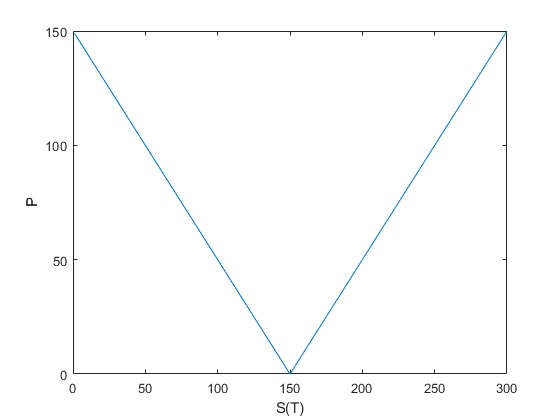

S = 1:300;
E = 150;

payoff = abs(S - E);

plot(payoff);
ylabel("P");
xlabel("S(T)")

The butterfly spread looks like:

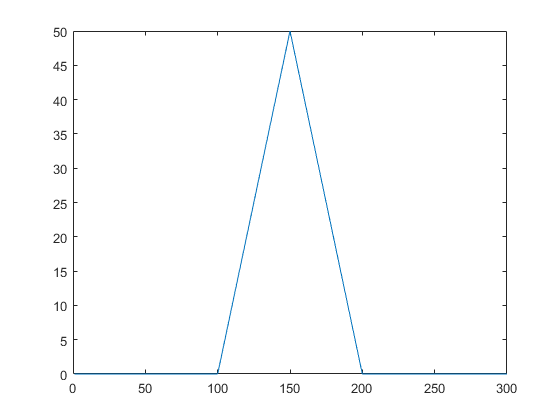

E1 = 100;
E3 = 200;

E2 = (E1 + E3)/2;

call1 = max(S - E1, 0);
call2 = max(S - E2, 0);
call3 = max(S - E3, 0);

profit = call1-2*call2+call3;
plot(profit);

The holder of the first situation would like the asset price to either be lower or higher than the initial price, the more it differs, the higher the profits.

The holder in the second situation would like the asset price to stay the same, as that is where the profits are the highest.

**Exercise 2:**

First, we plot all three formulas into one graph:

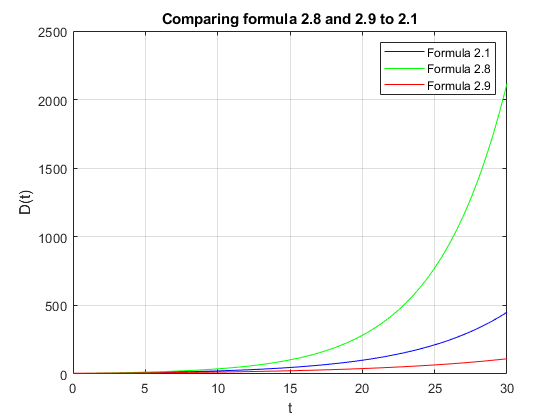

T = 30;
L = 60;
deltat = T/L;

clf 
dzero = 5; 
r=0.15; % Compound interest rate 
d28(1)=dzero; % formula 2.8
d29(1)=dzero; % formula 2.9
d(1)=0;


for i = 1:L % let run for L delta t periods
   tval(i+1) = i + 1; % time in years 
   d28(i+1) = (1 + r*(deltat^(1/2)))*d28(i); 
   d29(i+1) = (1 + r*(deltat^(3/2)))*d29(i); 
end

tcts = linspace(0,T,L+1); 
dcts = dzero*exp(r*tcts); 
plot(tcts,dcts,'b-') 
hold on 
plot(tcts,d28,'g-') 
plot(tcts,d29,'r-') 
grid on 
xlabel('t') 
ylabel('D(t)') 
title('Comparing formula 2.8 and 2.9 to 2.1') 
legend('Formula 2.1','Formula 2.8','Formula 2.9')
hold off

As can be seen in the figure below, formula 2.8 overestimates the result, whereas formula 2.9 underestimates it.

**Exercise 3:**

**Exercise 4:**

After downloading the datasets for two related coins in csv format from keggle.com, being Ethereum en Ethereum Classic, I imported them into MatLab using the following command:

%import data for ethereum
ethFileName = 'ethereum_price.csv';
ethTable = readtable(ethFileName);


%select correct rows
ethDateRow = ethTable{:, 'Date'};
y = ethTable{:, 'Open'};


%do the same for eth classic
ethClassicFileName = 'ethereum_classic_price.csv';
ethClassicTable = readtable(ethClassicFileName);


ethClassicDateRow = ethClassicTable{:, 'Date'};
y2 = ethClassicTable{:, 'Open'};

Indices = datefind(ethDateRow, ethClassicDateRow)

'datefind' requires Financial Toolbox.